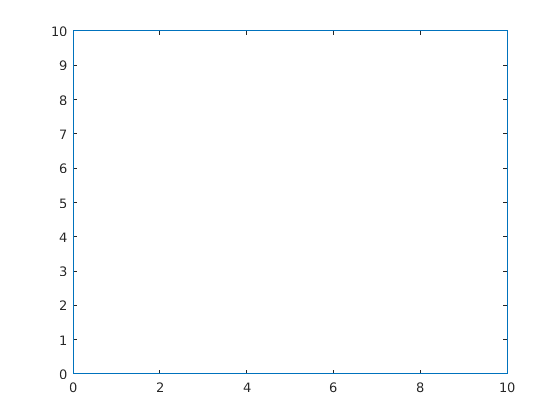

b=EV3();
b.connect('usb');

defaultSpeed = 10;

mx=b.motorA;
my=b.motorB;

mx.setProperties('power', defaultSpeed, 'speedRegulation', 1, 'limitValue', 0, 'brakeMode', 'Brake');
my.setProperties('power', defaultSpeed, 'speedRegulation', 1, 'limitValue', 0, 'brakeMode', 'Brake');

x_axis=[0,10,10,0,0];
y_axis=[0,0,10,10,0];

% r = 2;
% x_axis = -r:0.1:r;
% y_axis = sqrt(r^2-x_axis.^2);

y_dists = diff(y_axis);
x_dists = diff(x_axis);
tx = timer;
ty = timer;

xData.curPos = 0;
xData.tarPos = 0;
xData.power = 0;
xData.limit = 0;
xData.rounds = 0;
xData.m = mx;

yData.curPos = 0;
yData.tarPos = 0;
yData.power = 0;
yData.limit = 0;
yData.rounds = 0;
yData.m = my;

plot(x_axis,y_axis);

current_x=0;
current_y=0;

xtimer = timer;
ytimer = timer;

set(xtimer, 'TimerFcn', @timFcn, 'StartFcn', @timStartFcn, 'StopFcn', @timStopFcn, ...
    'ExecutionMode', 'fixedRate', 'Period', 0.05, 'UserData', xData);
set(ytimer, 'TimerFcn', @timFcn, 'StartFcn', @timStartFcn, 'StopFcn', @timStopFcn, ...
    'ExecutionMode', 'fixedRate', 'Period', 0.05, 'UserData', yData);

for i=1:length(x_dists)
    powers = powerRatio(x_dists(i), y_dists(i), defaultSpeed);
    xtimer.UserData.power = powers(1);
    ytimer.UserData.power = powers(2);
    
    [xAngle, xRounds] = convert(x_dists(i));
    xtimer.UserData.limit = xAngle;
    xtimer.UserData.rounds = xRounds;
    [yAngle, yRounds] = convert(y_dists(i));
    ytimer.UserData.limit = yAngle;
    ytimer.UserData.rounds = yRounds;
    
    xtimer.start();
    ytimer.start();
    
    while strcmp(xtimer.Running, 'on') || strcmp(ytimer.Running, 'on')
        pause(0.1)
    end
    
%     x_value = x_axis(i);
%     y_value = y_axis(i);
%     target_x = convert(x_value);
%     target_y = convert(y_value);


%     mx.limitValue = target_x;
%     my.limitValue = target_y;
%     mx.start;
%     my.start;
%     my.waitfor();
%     mx.waitfor();
%     mx.stop();
%     my.stop();
%     mx.resetTachoCount;
%     my.resetTachoCount;    

end

ans = int32
0

ans = 240

ans = 0

ans = int32
0

ans = 0

ans = 0

ans = int32
1

ans = 0

ans = 0

ans = int32
0

ans = 240

ans = 0

ans = int32
0

ans = 120

ans = 1

ans = int32
-1124

ans = 0

ans = 0

ans = int32
0

ans = 0

ans = 0

ans = int32
0

ans = 120

ans = 1


b.disconnect();

function [rounds, degrees] = convert(dist)
    %beispiel
    Faktor = 24; % = 360° / Zahnrad Umfang
    %degrees = distance_in_cm*360/10;
    angle = dist*Faktor;
    rounds = abs(floor(angle/360));
    while angle < 0
        angle = angle + 360;
    end
    degrees = mod(angle, 360);
end


function power = powerRatio(xDist, yDist, defaultSpeed)
    ratio = abs(yDist)/abs(xDist);
    if ratio == 0
        power = [defaultSpeed, 0];
    elseif ratio == inf
        power = [0, defaultSpeed];
    else
        power = [defaultSpeed, ratio * defaultSpeed];
    end
    power(1) = power(1) * xDist/abs(xDist);
    power(2) = power(2) * yDist/abs(yDist);
    power(isnan(power)) = 0;
end


function timStartFcn(t, e)
    myData = t.UserData;
    m = myData.m;
    m.internalReset();
    m.resetTachoCount();
    m.tachoCount()
    myData.rounds
    myData.limit
    if myData.rounds > 0
        m.limitValue = 0;
    else
        m.limitValue = myData.limit;
    end
    m.power = myData.power;
    m.start();
end

function timStopFcn(t, e)
    t.UserData.m.stop();
end

function timFcn(t, e)
    data = t.UserData;
    m = data.m;
    threshold = 180 + data.power/abs(data.power)*179;
    rounds = data.rounds;
    limit = data.limit;
    if rounds > 0
        if abs(data.m.tachoCount - threshold) < 1
            data.rounds = rounds - 1;
            if data.rounds == 0
                m.stop();
                m.limitValue = limit;
                m.start();
            end
        end
    end
    if abs(data.m.tachoCount - limit) < 1
        t.stop();
    end
end